Q2

clc
clear
close

% Variable definitions and system creation
m = 5; % Slider mass
M = 25000; % Container mass
l = 8; % Rope length 
g = 9.81; % Acceleration due to gravity

% System Matrix
A = [0 1 0 0; 0 0 (M*g/m) 0; 0 0 0 1; 0 0 -((1 + (M/m))*g/l) 0];
B = [0; 1/m; 0; -1/(m*l)];
C = [1 0 0 0];
D = 0;

sys = ss(A,B,C,D);

i. Step response

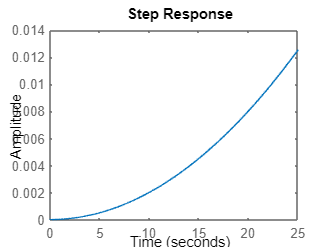

step(sys)

ii. State feedback control

poles = [-1 -2 -4 -8];
K = place(A,B,poles);

%check
eig(A-B*K)

ans =    -8.0000
   -4.0000
   -2.0000
   -1.0000


iii. Observer

new_poles = 5 * [-1 -2 -4 -8];
L = place(A',C', new_poles)';

iv. Close loop simulation

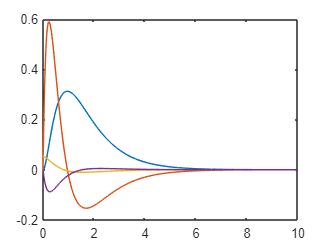

%Simulation of the closed loop system - no observer
x0 = [0; 0; pi/60; 0];

sys_fb = ss(A-B*K, B, C, D);

t = 0:0.01:10; 
u = 0*t; %no input

[y,~,x] = lsim(sys_fb,u,t,x0);
plot(t,x)

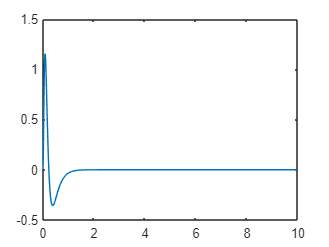


%Simulation of the closed loop system - observer included
A_hat = [A -B*K; L*C A-B*K-L*C];
B_hat = [B;B];
C_hat = [C -C];
D_hat = 0;

sys_hat = ss(A_hat, B_hat, C_hat, D_hat);
xxhat0 = [x0;[0;0;0;0]];

[ytilde,~,xxhat] = lsim(sys_hat,u,t,xxhat0);
plot(t,ytilde);

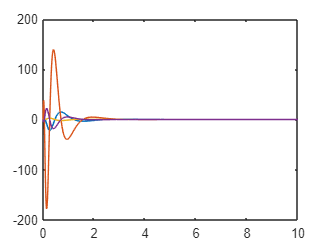

plot(t,xxhat(:,1:4));